# MPC Assignment 1 - Alireza Amiri

## 1

### 1.1

#### 1.1.1

% Step 1: Find the intersections of the lines
% Solve pairs of equations symbolically for intersections
syms x1 x2

% Line equations:
eq1 = x1 + 2*x2 == 8;          % From x1 + 2*x2 = 8
eq2 = 3*x1 + 2*x2 == 12;       % From 3*x1 + 2*x2 = 12
eq3 = x1 + x2 == 4;            % From x1 + x2 = 4

% Solve intersections
% Intersection of eq1 and eq2
sol_1_2 = solve([eq1, eq2], [x1, x2]);

% Intersection of eq1 and eq3
sol_1_3 = solve([eq1, eq3], [x1, x2]);

% Intersection of eq2 and eq3
sol_2_3 = solve([eq2, eq3], [x1, x2]);

% Step 2: Identify intercepts with axes
% x1 intercepts and x2 intercepts
intercept_x1 = solve(eq1, x1);   % x1-intercept of x1 + 2*x2 = 8
intercept_x2 = solve(eq2, x1);   % x1-intercept of 3*x1 + 2*x2 = 12

% Boundary points on axes
boundary_points = [0, 8/2; 4, 0]; % Intersections with axes: (0, 8/2), (4, 0)

% Collect all intersection points
points = [
    double([sol_1_2.x1, sol_1_2.x2]);  % Intersection of eq1 and eq2
    double([sol_1_3.x1, sol_1_3.x2]);  % Intersection of eq1 and eq3
    double([sol_2_3.x1, sol_2_3.x2]);  % Intersection of eq2 and eq3
    boundary_points                     % Intersection with axes
];

% Step 3: Objective function
f = @(x1, x2) 5*x1 + 6*x2;

% Evaluate the objective function at each point
f_vals = arrayfun(@(i) f(points(i, 1), points(i, 2)), 1:size(points, 1));

% Find the minimum value and corresponding point
[min_val, min_idx] = min(f_vals);
optimal_point = points(min_idx, :);

% Display the results
fprintf('Intersection points and corresponding function values:\n');

Intersection points and corresponding function values:


for i = 1:size(points, 1)
    fprintf('Point (x1 = %.2f, x2 = %.2f), f(x1, x2) = %.2f\n', points(i, 1), points(i, 2), f_vals(i));
end

Point (x1 = 2.00, x2 = 3.00), f(x1, x2) = 28.00
Point (x1 = 0.00, x2 = 4.00), f(x1, x2) = 24.00
Point (x1 = 4.00, x2 = 0.00), f(x1, x2) = 20.00
Point (x1 = 0.00, x2 = 4.00), f(x1, x2) = 24.00
Point (x1 = 4.00, x2 = 0.00), f(x1, x2) = 20.00


fprintf('Optimal point: (x1 = %.2f, x2 = %.2f), Minimum f(x1, x2) = %.2f\n', optimal_point(1), optimal_point(2), min_val);

Optimal point: (x1 = 4.00, x2 = 0.00), Minimum f(x1, x2) = 20.00


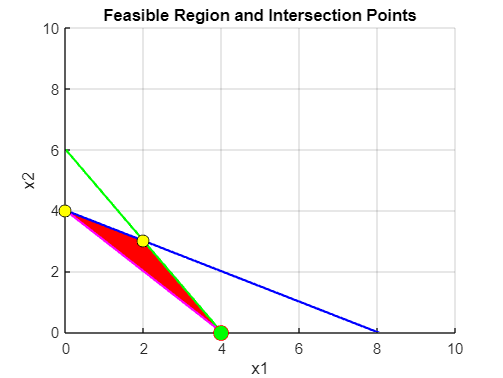


% Step 4: Plot the feasible region and the intersection points
figure; hold on;

% Plot the feasible region
contourf(X1, X2, feasible_region, [1 1], 'FaceColor', 'r', 'EdgeColor', 'none');

% Plot the lines representing the inequalities
plot(x1_vals, (8 - x1_vals)/2, 'b', 'LineWidth', 1.5);     % x1 + 2*x2 = 8
plot(x1_vals, (12 - 3*x1_vals)/2, 'g', 'LineWidth', 1.5);  % 3*x1 + 2*x2 = 12
plot(x1_vals, 4 - x1_vals, 'm', 'LineWidth', 1.5);         % x1 + x2 = 4

% Plot intersection points
plot(points(:, 1), points(:, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);

% Highlight the optimal point
plot(optimal_point(1), optimal_point(2), 'ro', 'MarkerFaceColor', 'g', 'MarkerSize', 10);

% Add labels and title
xlabel('x1');
ylabel('x2');
title('Feasible Region and Intersection Points');
grid on;
hold off;

xlim([0 10])
ylim([0 10])

#### 1.1.2: Using Yalmip

yalmip('clear')
x1 = sdpvar(1,1)

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1


x2 = sdpvar(1,1)

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1



constraints = [x1<=8-2*x2 , 3*x1 + 2*x2<= 12, x1 + x2>=4 , x1>=0 , x2 >=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                    Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality 1x1|              1 to 8|
|   #2|   Element-wise inequality 1x1|             2 to 12|
|   #3|   Element-wise inequality 1x1|              1 to 4|
|   #4|   Element-wise inequality 1x1|              1 to 1|
|   #5|   Element-wise inequality 1x1|              1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



obj = 5*x1 + 6*x2

Linear scalar (real, 2 variables)
Coefficients range: 5 to 6



sol = optimize(constraints , obj)

Optimal solution found.



sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '9.13.0.2166757 (R2022b) Update 4'
       yalmiptime: 0.0452
       solvertime: 0.0068
             info: 'Successfully solved (LINPROG)'
          problem: 0



if sol.problem ==0
    val1 = value(x1)
    val2 = value(x2)
    objvalue = value(obj)
end

val1 = 4.0000

val2 = 0

objvalue = 20.0000

#### 1.1.3: Using CVX

cvx_begin

variables x1 x2

% Objective function
minimize(5*x1 + 6*x2)

% Subject to the constraints
subject to
    x1 + 2*x2 <= 8
    3*x1 + 2*x2 <= 12
    x1 + x2 >= 4
    x1 >= 0
    x2 >= 0

cvx_end

% Display the results
x1_value = x1
x2_value = x2

% Clear previous variables
clear; clc;

% Step 1: Define symbolic variables
syms x1 x2;

% Step 2: Define the constraints
% Lines based on constraints
eq1 = x1 + x2 == -20;  % From x1 + x2 = -20
eq2 = x1 + x2 == 5;    % From x1 + x2 = 5

% Step 3: Solve intersections
% Intersection of eq1 and eq2
sol_1_2 = solve([eq1, eq2], [x1, x2]);

% Define boundaries for x1 and x2
boundary_x1 = [-5, 5];  % x1 boundaries
boundary_x2 = [-1, 5];  % x2 boundaries

% Collect boundary points based on the constraints
boundary_points = [
    -5, -1;   % Bottom left corner
    -5, 5;    % Top left corner
    5, -1;    % Bottom right corner
    0, 5;     % Top right corner
    5,0
];

% Collect all intersection points (if valid)
points = [
    double([sol_1_2.x1, sol_1_2.x2]);  % Intersection of eq1 and eq2
    boundary_points                     % Intersections with axes
];

% Step 4: Define the objective function
f = @(x1, x2) abs(x1 - 5) + abs(x2 - 5);

% Step 5: Evaluate the objective function at each point
% Filter valid points based on constraints
valid_points = points((points(:,1) >= boundary_x1(1)) & (points(:,1) <= boundary_x1(2)) & ...
                      (points(:,2) >= boundary_x2(1)) & (points(:,2) <= boundary_x2(2)), :);

f_vals = arrayfun(@(i) f(valid_points(i, 1), valid_points(i, 2)), 1:size(valid_points, 1));

% Step 6: Find the minimum value and corresponding point
[min_val, min_idx] = min(f_vals);
optimal_point = valid_points(min_idx, :);

% Display the results
fprintf('Valid points and corresponding function values:\n');

Valid points and corresponding function values:


for i = 1:size(valid_points, 1)
    fprintf('Point (x1 = %.2f, x2 = %.2f), f(x1, x2) = %.2f\n', valid_points(i, 1), valid_points(i, 2), f_vals(i));
end

Point (x1 = -5.00, x2 = -1.00), f(x1, x2) = 16.00
Point (x1 = -5.00, x2 = 5.00), f(x1, x2) = 10.00
Point (x1 = 5.00, x2 = -1.00), f(x1, x2) = 6.00
Point (x1 = 0.00, x2 = 5.00), f(x1, x2) = 5.00
Point (x1 = 5.00, x2 = 0.00), f(x1, x2) = 5.00


fprintf('Optimal point: (x1 = %.2f, x2 = %.2f), Minimum f(x1, x2) = %.2f\n', optimal_point(1), optimal_point(2), min_val);

Optimal point: (x1 = 0.00, x2 = 5.00), Minimum f(x1, x2) = 5.00


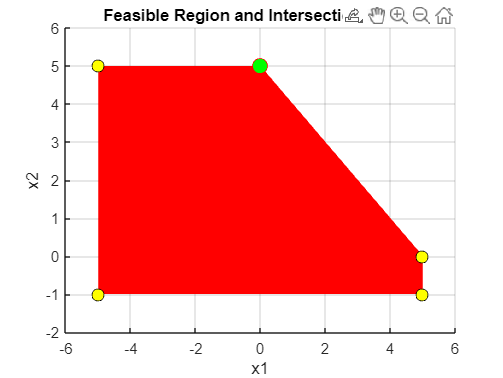


% Step 7: Plot the feasible region and the intersection points
figure; hold on;

% Create a grid for plotting feasible region
[x1_vals, x2_vals] = meshgrid(-5:0.1:5, -1:0.1:5);
feasible_region = (x1_vals + x2_vals >= -20) & (x1_vals + x2_vals <= 5 & ...
                  (-5 <= x1_vals) & (x1_vals <= 5) & (-1 <= x2_vals) & (x2_vals <= 5));

% Plot the feasible region
contourf(x1_vals, x2_vals, feasible_region, [1 1], 'FaceColor', 'r', 'EdgeColor', 'none');

% Plot the constraint lines
plot(x1_vals, -20 - x1_vals, 'k', 'LineWidth', 1.5); % x1 + x2 = -20
plot(x1_vals, 5 - x1_vals, 'k', 'LineWidth', 1.5);   % x1 + x2 = 5

% Plot intersection points
plot(valid_points(:, 1), valid_points(:, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);

% Highlight the optimal point
plot(optimal_point(1), optimal_point(2), 'ro', 'MarkerFaceColor', 'g', 'MarkerSize', 10);

% Add labels and title
xlabel('x1');
ylabel('x2');
title('Feasible Region and Intersection Points');
grid on;
hold off;

% Set axis limits
xlim([-6 6]);
ylim([-2 6]);

% Clear previous variables
clear; clc;

% Step 1: Define the variables
x1 = sdpvar(1,1);  % Decision variable x1
x2 = sdpvar(1,1);  % Decision variable x2

% Step 2: Define the objective function
objective = abs(x1 - 5) + abs(x2 - 5);

% Step 3: Define the constraints
constraints = [
    -5 <= x1 <= 5,      % Constraint for x1
    -1 <= x2 <= 5,      % Constraint for x2
    -20 <= x1 + x2 <= 5 % Constraint for the sum of x1 and x2
];

% Step 4: Solve the optimization problem
options = sdpsettings('verbose', 1);  % Set verbosity to see solver output
sol = optimize(constraints, objective, options);

Optimal solution found.




% Step 5: Check the results
if sol.problem == 0
    % If no error, display the results
    optimal_x1 = value(x1);
    optimal_x2 = value(x2);
    optimal_value = value(objective);

    fprintf('Optimal point: (x1 = %.2f, x2 = %.2f), Minimum f(x1, x2) = %.2f\n', ...
        optimal_x1, optimal_x2, optimal_value);
else
    % If there was an error, display the error message
    disp('Solver encountered an issue:');
    disp(sol.info);
end

Optimal point: (x1 = 5.00, x2 = 0.00), Minimum f(x1, x2) = 5.00


% Clear previous variables
clear; clc;

% Step 1: Start CVX
cvx_begin

    % Step 2: Define the variables
    variables x1 x2;  % Decision variables x1 and x2

    % Step 3: Define the objective function
    minimize(abs(x1 - 5) + abs(x2 - 5));

    % Step 4: Define the constraints
    subject to
        -5 <= x1 <= 5;      % Constraint for x1
        -1 <= x2 <= 5;      % Constraint for x2
        -20 <= x1 + x2 <= 5; % Constraint for the sum of x1 and x2

cvx_end

 
Calling SDPT3 4.0: 10 variables, 4 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  4
 dim. of socp   var  =  4,   num. of socp blk  =  2
 dim. of linear var  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.4e-01|1.9e+00|1.5e+03| 4.100000e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.783|1.000|5.3e-02|1.1e-02|2.8e+02| 2.235904e+02 -4.906071e+01| 0:0:00| chol  1  1 
 2|0.932|0.954|3.6e-03|1.2e-02|1.9e+01| 5.515023e+00 -1.274188e+01| 0:0:00| chol  1  1 
 3|1.000|0.768|2.4e-07|3.6e-03|7.4e+00


% Step 5: Display the results
fprintf('Optimal point: (x1 = %.2f, x2 = %.2f), Minimum f(x1, x2) = %.2f\n', x1, x2, abs(x1 - 5) + abs(x2 - 5));

Optimal point: (x1 = 2.32, x2 = 2.68), Minimum f(x1, x2) = 5.00
